# Throughput performance: LoS vs NLoS

## Clear the workspace

clear;
clc;
close all;

## System parameters

numCandiRelays_i = [1152, 2384, 3644];
numCandiRelays_s = ["1152", "2384", "3644"];
DataClass_s = ["Capacity","Paths","Sequence"];
BeamWidth_i = [5,7,9,11,13,15];
seedNum_i = 100; % focusing on 500-599 seeds

## File paths

dataPath_s = '../../Data/';
relayPath_s = '../../Data/Relays/';
bsPath_s = '../../Data/Base_Stations/';
pathPath_1Mbs_200_s = '../../Data/Paths/Single_MBS/200/';
pathPath_1Mbs_300_s = '../../Data/Paths/Single_MBS/300/';
pathPath_1Mbs_Ltd_s = '../../Data/Paths/Single_MBS_LimitedArea/200/';
pathPath_2Mbs_200_s = '../../Data/Paths/Double_MBS/200/';
pathPath_2Mbs_300_s = '../../Data/Paths/Double_MBS/300/';
pathPath_2Mbs_Ltd_s = '../../Data/Paths/Double_MBS_LimitedArea/200/';

## Grid = 300m, Single_MBS, 5 degree beam, 3644 relays

% relayCoords_f = readRelaysFromFile(strcat(dataPath_s, relayPath_s), 'relay', seedNum_i, numCandiRelays_i);
% bsCoords_f = readBssFromFile(strcat(dataPath_s, bsPath_s), seedNum_i);
result = [];
fileList = dir(pathPath_1Mbs_300_s);
files = fileList(3:end);
fileList_bs_nb = dir('../../Data/BS_Neighbors/');
file_bs_nb = fileList_bs_nb(3:103);
for i = 2:3:length(files)
    % iterate each file
    filename = files(i).name;
    [filepath,name,ext] = fileparts(filename);
    paras = strsplit(name,'_');
    % 'Data_Results_500_1152_22_11_Capacity.txt'
    beam = str2num(paras{6});
    if beam ~= 5
        continue;
    end
    index = str2num(paras{3}) - 499;
    numRelays = str2num(paras{4});
    density = idivide(numRelays, int32(1000));
    density_f = num2str(0.000100 * double(density), '%.6f');
    pathPath = strcat(pathPath_1Mbs_300_s, filename);
    relayPath = strcat(relayPath_s, 'Data_Relays_Surface_', paras{3}, '_', density_f, '_', num2str(density),'.txt');
    bsPath = strcat(bsPath_s, 'Data_BSSet_', paras{3}, '_', paras{4}, '_300.000000_5.txt');
    bsNeighborPath = strcat('../../Data/BS_Neighbors/', file_bs_nb(index).name);
    pathSeqPath = strcat(pathPath_1Mbs_300_s, files(i+1).name);
    [capPath, demand, totalDemand, subtree] = getPathInfo(pathSeqPath,relayPath,bsPath,bsNeighborPath,pathPath,true);
    demand = demand(find(demand~=0));
    demand = reshape(demand, [], 2);
    totalDemand = totalDemand(find(totalDemand~=0));
    totalDemand = reshape(totalDemand, [], 2);
    result = [result; min(demand)];
    
end

result_200 = [];
fileList = dir(pathPath_1Mbs_Ltd_s);
files = fileList(3:end);
fileList_bs_nb = dir('../../Data/BS_Neighbors/');
file_bs_nb = fileList_bs_nb(3:103);
for i = 2:3:length(files)
    % iterate each file
    filename = files(i).name;
    [filepath,name,ext] = fileparts(filename);
    paras = strsplit(name,'_');
    % 'Data_Results_500_1152_22_11_Capacity.txt'
    beam = str2num(paras{6});
%     if beam ~= 5
%         continue;
%     end
    index = str2num(paras{3}) - 499;
    if index > 100
        continue;
    end
    if index == 46
        continue;
    end
    numRelays = str2num(paras{4});
    density = idivide(numRelays, int32(1000));
    density_f = num2str(0.000100 * double(density), '%.6f');
    pathPath = strcat(pathPath_1Mbs_Ltd_s, filename);
    relayPath = strcat(relayPath_s, 'Data_Relays_Surface_', paras{3}, '_', density_f, '_', num2str(density),'.txt');
    bsPath = strcat(bsPath_s, 'Data_BSSet_', paras{3}, '_', paras{4}, '_200.000000_5.txt');
    bsNeighborPath = strcat('../../Data/BS_Neighbors/', file_bs_nb(index).name);
    pathSeqPath = strcat(pathPath_1Mbs_Ltd_s, files(i+1).name);
    [capPath, demand, totalDemand, subtree] = getPathInfo(pathSeqPath,relayPath,bsPath,bsNeighborPath,pathPath,true);
    demand = demand(find(demand~=0));
    demand = reshape(demand, [], 2);
    totalDemand = totalDemand(find(totalDemand~=0));
    totalDemand = reshape(totalDemand, [], 2);
    result_200 = [result_200; min(demand)];
    
end

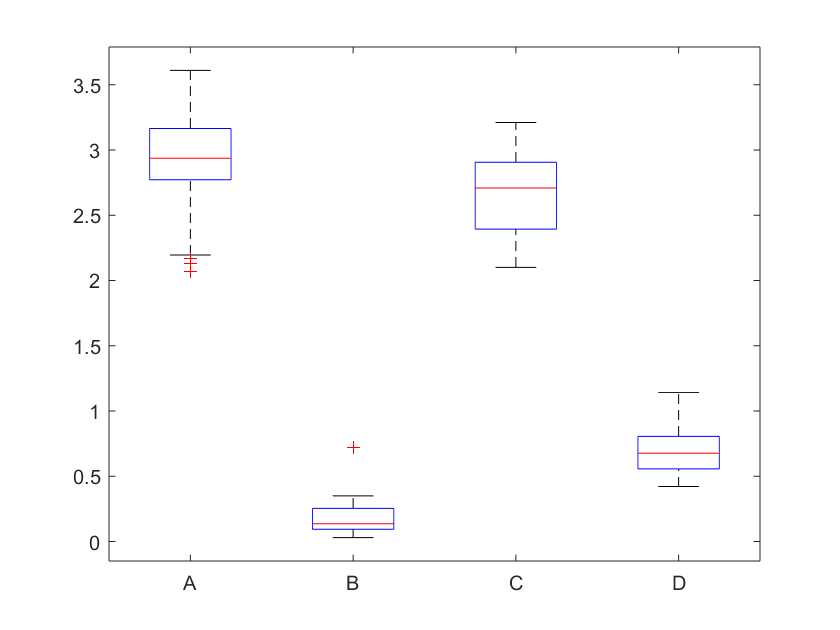

figure;
A = result(:,1);
B = result(:,2);
C = result_200(:,1);
D = result_200(:,2);
group = [    ones(size(A));
         2 * ones(size(B));
         3 * ones(size(C));
         4 * ones(size(D))];
figure
boxplot([A; B; C; D],group)
set(gca,'XTickLabel',{'A','B','C','D'})

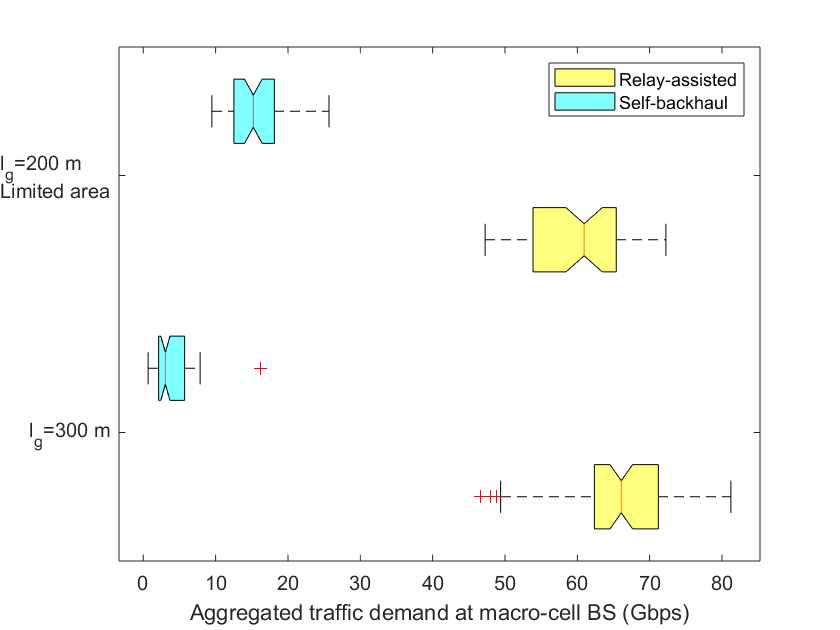

figure;
A = result(:,1);
B = result(:,2);
C = result_200(:,1);
D = result_200(:,2);
group = [    ones(size(A));
         2 * ones(size(B));
         3 * ones(size(C));
         4 * ones(size(D))];
positions = [1 1.25 1.5 1.75];
boxplot([A;B;C;D]*22.5, group, 'positions', positions, "Orientation","horizontal",'Notch',"on");

set(gca,'ytick',[mean(positions(1:2)) mean(positions(3:4)) ])
set(gca,'yticklabel',{'l_g=300 m', 'l_g=200 m\newlineLimited area'}, 'TickLabelInterpreter', 'tex')

color = ['c', 'y', 'c', 'y'];
h = findobj(gca,'Tag','Box');
for j=1:length(h)
   patch(get(h(j),'XData'),get(h(j),'YData'),color(j),'FaceAlpha',.5);
end

c = get(gca, 'Children');

hleg1 = legend(c(1:2), 'Relay-assisted', 'Self-backhaul' );
xlabel('Aggregated traffic demand at macro-cell BS (Gbps)' );